# Compare Prediction Intervals of GPR Models

This example fits GPR models to a noise-free data set and a noisy data set. The example compares the predicted responses and prediction intervals of the two fitted GPR models. 

Generate two observation data sets from the function $g\left(x\right)=x\cdot \sin \left(x\right)$. 

rng('default') % For reproducibility
x_observed = linspace(0,10,21)';
y_observed1 = x_observed.*sin(x_observed);
y_observed2 = y_observed1 + 0.5*randn(size(x_observed));

The values in `y_observed1` are noise free, and the values in `y_observed2` include some random noise. 

Fit GPR models to the observed data sets.

gprMdl1 = fitrgp(x_observed,y_observed1);
gprMdl2 = fitrgp(x_observed,y_observed2);

Compute the predicted responses and 95% prediction intervals using the fitted models. 

x = linspace(0,10)';
[ypred1,~,yint1] = predict(gprMdl1,x);
[ypred2,~,yint2] = predict(gprMdl2,x);

Resize a figure to display two plots in one figure.

fig = figure;
fig.Position(3) = fig.Position(3)*2;

Create a 1-by-2 tiled chart layout.

tiledlayout(1,2,'TileSpacing','compact')

For each tile, draw a scatter plot of observed data points and a function plot of $x\cdot \sin \left(x\right)$. Then add a plot of GP predicted responses and a patch of prediction intervals. 

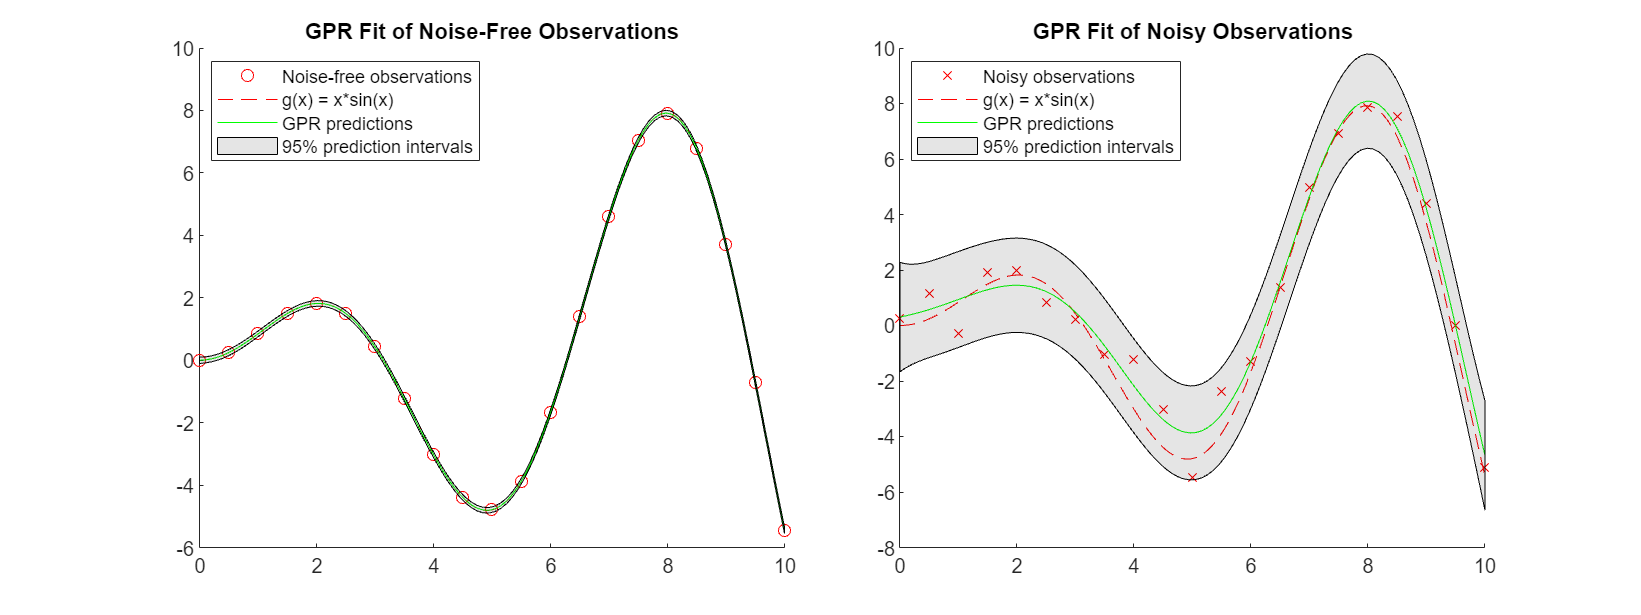

nexttile
hold on
scatter(x_observed,y_observed1,'r') % Observed data points
fplot(@(x) x.*sin(x),[0,10],'--r')  % Function plot of x*sin(x)
plot(x,ypred1,'g')                  % GPR predictions
patch([x;flipud(x)],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noise-Free Observations')
legend({'Noise-free observations','g(x) = x*sin(x)','GPR predictions','95% prediction intervals'},'Location','best')

nexttile
hold on
scatter(x_observed,y_observed2,'xr') % Observed data points
fplot(@(x) x.*sin(x),[0,10],'--r')   % Function plot of x*sin(x)
plot(x,ypred2,'g')                   % GPR predictions
patch([x;flipud(x)],[yint2(:,1);flipud(yint2(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noisy Observations')
legend({'Noisy observations','g(x) = x*sin(x)','GPR predictions','95% prediction intervals'},'Location','best')

When the observations are noise free, the predicted responses of the GPR fit cross the observations. The standard deviation of the predicted response is almost zero. Therefore, the prediction intervals are very narrow. When observations include noise, the predicted responses do not cross the observations, and the prediction intervals become wide. 

*Copyright 2020 The MathWorks, Inc.*